# Load DNA Image and Trace Molecules

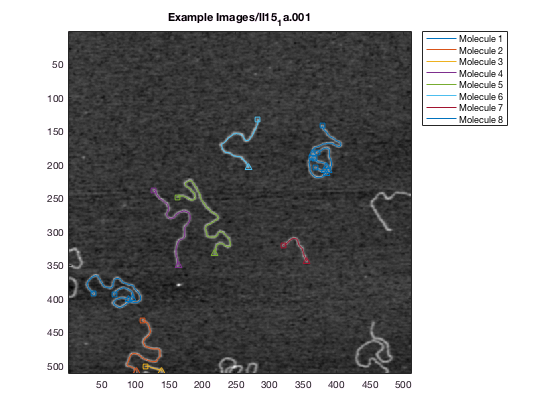

TraceData = DNAtracer('Example Images/ll15_1a.001');

title('Example Images/ll15_1a.001');

## Construct CR-Spline for each molecule segment

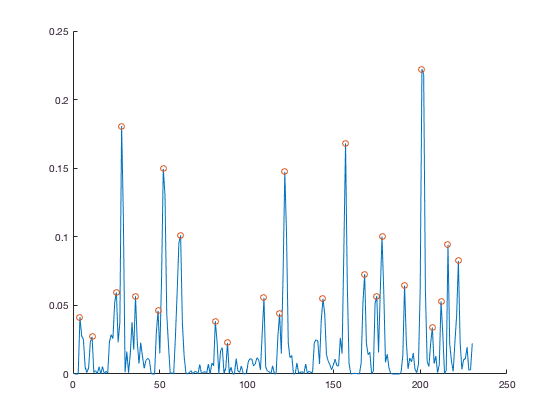

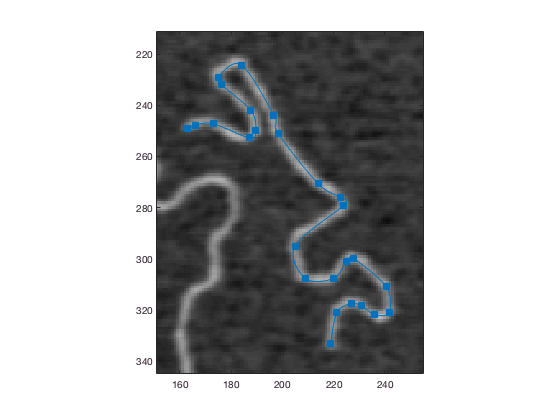

MOL_ID = 5; %molecule to plot
%Finit Difference Coefficients
D1 = [1/280	-4/105	1/5	-4/5	0	4/5	-1/5	4/105	-1/280];
D2 = [-1/560	8/315	-1/5	8/5	-205/72	8/5	-1/5	8/315	-1/560];


figure(2);clf;
gca;
hold on;

figure(3);clf;
gca;
imagesc(TraceData.im_data_flat);
axis image;
colormap gray;
hold on;

for n=1:numel(TraceData.MoleculeData)
    %check if cspline need to be computed
    COMPUTE_CSPLINE = true;%~isfield(TraceData.MoleculeData(n).Segment,'cspline');
    
    for j=1:numel(TraceData.MoleculeData(n).Segment)
        
        if COMPUTE_CSPLINE
            XY = TraceData.MoleculeData(n).Segment(j).XY;
            %S = cumsum(sqrt(sum(diff(XY,1,1).^2,2)),1);
            %S = [0;S];
            S = 1:size(XY,1);
            pp = csaps(S,XY',0.5);
            
            TraceData.MoleculeData(n).Segment(j).cspline.s = S;
            TraceData.MoleculeData(n).Segment(j).cspline.pp = pp;
                
            
        end
        S = TraceData.MoleculeData(n).Segment(j).cspline.s;
        XY = fnval(TraceData.MoleculeData(n).Segment(j).cspline.pp,S)'; %xy points of segments from cspline
        
        dXY = filter(D1,1,XY);
        ddXY = filter(D2,1,XY);
        
        %curvature
        k2 = ((dXY(:,1).*ddXY(:,2) - dXY(:,2).*ddXY(:,1))./(dXY(:,1).^2 + dXY(:,2).^2).^(3/2)).^2;
        k2=k2(5:end); %filter shifts to the right, correct that
        %find peaks in curvature to detemine CR-Spline node locations
        [~,locs] = findpeaks(k2,'MinPeakDistance',2,'MinPeakProminence',0.02);

        if n==MOL_ID %plot curvature for selected molecule
            figure(2);
            plot(S(1:end-4),k2);
            
            plot(S(locs),k2(locs),'o');
        end
        
        %Add end points to list of node if needed
        if ~ismember(1,locs)
            locs = [1;locs];
        end
        if ~ismember(numel(S),locs)
            locs=[locs;numel(S)];
        end
        
        %Create Catmull-Rom spline
        TraceData.MoleculeData(n).Segment(j).CRspline = crspline(XY(locs,1),XY(locs,2));
        
        if n==MOL_ID
            figure(3);
            plot(TraceData.MoleculeData(n).Segment(j).CRspline,'Interactive',true);
            if j==1
                subimg = TraceData.MoleculeData(n).SubImg+[-10,-10;10,10];
                xlim(subimg(:,2));
                ylim(subimg(:,1));
            end
        end
        
    end
end